Michal Szabo

31.12.2021

# Extra assignment: Crane

The non linear model of the crane presented in figure 1 is available in file modelcomplet.mdl with parameters defined in parameters.m Crane/inverted pendulum . The available measurements are the crane position and angle (x1 and x2).

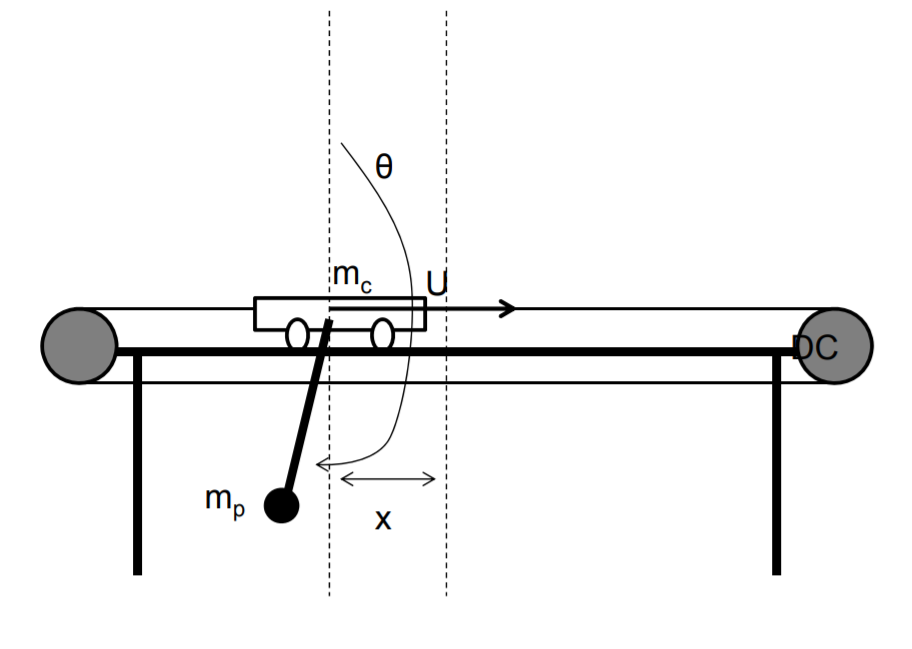

Figure. 1: Crane

Where the system in state-space representation is


$$\left\lbrack \begin{array}{c}
x_1^{\prime } \\
x_2^{\prime } \\
x_3^{\prime } \\
x_4^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
0 & -0\ldotp 4480 & -0\ldotp 5891 & -0\ldotp 0085\\
0 & -26\ldotp 6835 & -1\ldotp 6790 & -0\ldotp 5067
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
17\ldotp 5188\\
49\ldotp 9321
\end{array}\right\rbrack u$$



$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack$$


Given the script *simulation_models *and *three_models_observer *simulink file we can see how to represent this model in multiple ways. We also got a linear observer for our crane model.

% Parameters
mc=1.12; mp=0.095;
L=0.36;
g=9.81;
Um=0.5;
DZu=0.4; DZpv=3.6; DZcp=6.8; DZcv=0.08;
fp=0.0038;
J=0.0075;
l=0.0167903;
mu=l*(mc+mp);
Fs=2.75;
a=-l^2+J/(mc+mp);
M=22.304;
Fc=0.75;
FSD=2.7457; FSU=2.7972; FCU=0.8793; FCD=0.2501;
Xc=2; Yc=2;
FS=2;
FSul=2; FSdl=-1;

%linearisation
A=[0 0 1 0;0 0 0 1;0 -l*mu*g/J -a*Fc/J -l*fp/J;0 -mu*g/J -l*Fc/J -fp/J]

A =          0         0    1.0000         0
         0         0         0    1.0000
         0   -0.4480   -0.5891   -0.0085
         0  -26.6835   -1.6790   -0.5067


B=[0;0;a/J;l/J]

B =          0
         0
    0.7855
    2.2387


C=[1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1];
D=[0;0;0;0];


%transfer function
[num,den]=ss2tf(A,B,C,D);

%Discretisation
A1=expm(A(2:4,2:4)*0.1);
B1=(A1-eye(3))*(A(2:4,2:4))'*B(2:4);

%Observer
L=place(A',[1 0 0 0;0 1 0 0]',[-5,-5.1,-5.2,-5.3]);
L=L'

L =     9.7199   -0.0964
   -1.7918    9.7843
   20.8507   -0.9272
  -15.9932   -5.0103



sim('three_models_observer')

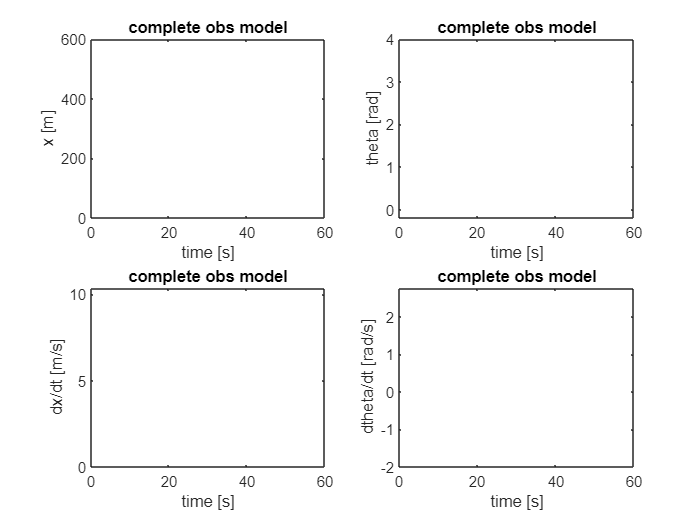



%simulation of the complete model
figure
subplot(2,2,1)
plot(x(:,1),x(:,2))
xlabel('time [s]')
ylabel('x [m]')
title('complete model')
subplot(2,2,2)
plot(x1(:,1),theta(:,2))
xlabel('time [s]')
ylabel('theta [rad]')
title('complete model')
subplot(2,2,3)
plot(x(:,1),dx(:,2))
xlabel('time [s]')
ylabel('dx/dt [m/s]')
title('complete model')
subplot(2,2,4)
plot(x(:,1),dtheta(:,2))
xlabel('time [s]')
ylabel('dtheta/dt [rad/s]')
title('complete model')

%simulation of the non-linear model
figure
subplot(2,2,1)
plot(x(:,1),x(:,2))
hold on
plot(x(:,1),x1(:,2),'r')
xlabel('time [s]')
ylabel('x [m]')
title('complete nl model')
subplot(2,2,2)
plot(x(:,1),theta(:,2))
hold on
plot(x(:,1),theta1(:,2),'r')
xlabel('time [s]')
ylabel('theta [rad]')
title('complete nl model')
subplot(2,2,3)
plot(x(:,1),dx(:,2))
hold on
plot(x(:,1),dx1(:,2),'r')
xlabel('time [s]')
ylabel('dx/dt [m/s]')
title('complete nl model')
subplot(2,2,4)
plot(x(:,1),dtheta(:,2))
hold on
plot(x(:,1),dtheta1(:,2),'r')
xlabel('time [s]')
ylabel('dtheta/dt [rad/s]')
title('complete nl model')

%simulation of the linear model
figure
subplot(2,2,1)
plot(x(:,1),x(:,2))
hold on
plot(x(:,1),x2(:,2),'r')
xlabel('time [s]')
ylabel('x [m]')
title('complete l model')
subplot(2,2,2)
plot(x(:,1),theta(:,2))
hold on
plot(x(:,1),theta2(:,2),'r')
xlabel('time [s]')
ylabel('theta [rad]')
title('complete l model')
subplot(2,2,3)
plot(x(:,1),dx(:,2))
hold on
plot(x(:,1),dx2(:,2),'r')
xlabel('time [s]')
ylabel('dx/dt [m/s]')
title('complete l model')
subplot(2,2,4)
plot(x(:,1),dtheta(:,2))
hold on
plot(x(:,1),dtheta2(:,2),'r')
xlabel('time [s]')
ylabel('dtheta/dt [rad/s]')
title('complete l model')

%simulation of the transfer function
figure
subplot(2,2,1)
plot(x(:,1),x(:,2))
hold on
plot(x(:,1),x3(:,2),'r')
xlabel('time [s]')
ylabel('x [m]')
title('complete tf model')
subplot(2,2,2)
plot(x(:,1),theta(:,2))
hold on
plot(x(:,1),theta3(:,2),'r')
xlabel('time [s]')
ylabel('theta [rad]')
title('complete tf model')
subplot(2,2,3)
plot(x(:,1),dx(:,2))
hold on
plot(x(:,1),dx3(:,2),'r')
xlabel('time [s]')
ylabel('dx/dt [m/s]')
title('complete tf model')
subplot(2,2,4)
plot(x(:,1),dtheta(:,2))
hold on
plot(x(:,1),dtheta3(:,2),'r')
xlabel('time [s]')
ylabel('dtheta/dt [rad/s]')
title('complete tf model')

%simulation discrete
figure
subplot(2,2,1)
plot(x(:,1),x(:,2))
hold on
plot(x4(:,1),x4(:,2),'r')
xlabel('time [s]')
ylabel('x [m]')
title('complete disc model')
subplot(2,2,2)
plot(x(:,1),theta(:,2))
hold on
plot(x4(:,1),theta4(:,2),'r')
xlabel('time [s]')
ylabel('theta [rad]')
title('complete disc model')
subplot(2,2,3)
plot(x(:,1),dx(:,2))
hold on
plot(x4(:,1),dx4(:,2),'r')
xlabel('time [s]')
ylabel('dx/dt [m/s]')
title('complete disc model')
subplot(2,2,4)
plot(x(:,1),dtheta(:,2))
hold on
plot(x4(:,1),dtheta4(:,2),'r')
xlabel('time [s]')
ylabel('dtheta/dt [rad/s]')
title('complete disc model')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
sim('Observer')

figure
subplot(2,2,1)
plot(x(:,1),x(:,2))
hold on
plot(x(:,1),x6(:,2),'r')
xlabel('time [s]')
ylabel('x [m]')
title('complete obs model')
subplot(2,2,2)
plot(x(:,1),theta(:,2))
hold on
plot(x(:,1),theta6(:,2),'r')
xlabel('time [s]')
ylabel('theta [rad]')
title('complete obs model')
subplot(2,2,3)
plot(x(:,1),dx(:,2))
hold on
plot(x(:,1),dx6(:,2),'r')
xlabel('time [s]')
ylabel('dx/dt [m/s]')
title('complete obs model')
subplot(2,2,4)
plot(x(:,1),dtheta(:,2))
hold on
plot(x(:,1),dtheta6(:,2),'r')
xlabel('time [s]')
ylabel('dtheta/dt [rad/s]')
title('complete obs model')

## Discrete observer

### a) Defining sample time

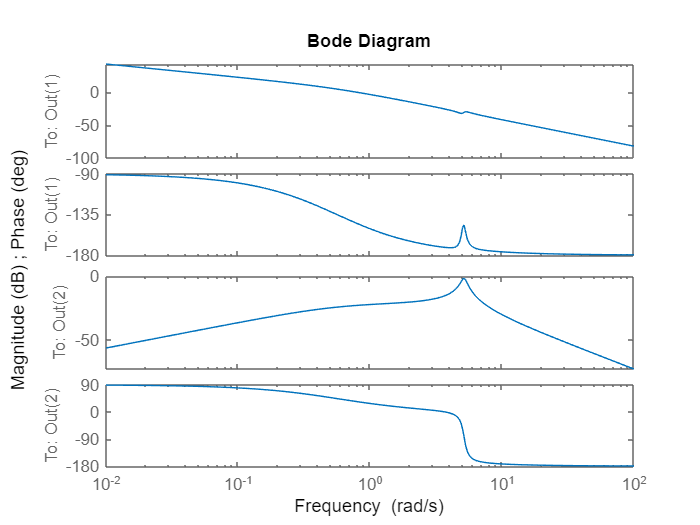

A=[0 0 1 0;0 0 0 1;0 -l*mu*g/J -a*Fc/J -l*fp/J;0 -mu*g/J -l*Fc/J -fp/J];
B=[0;0;a/J;l/J];
C=[1 0 0 0;0 1 0 0];
D=0;

sys = ss(A,B,C,D);
figure
bodeplot(sys);

We create a bodeplot and we try to find a bandwidth (-3dB). Then we can apply the rule of thumb with the following equation.


$$\frac{1}{T_s }>30*\textrm{bandwidth}\;\textrm{of}\;\textrm{the}\;\textrm{system}$$


Where the -3dB bandwith is around the frequency of 3Hz and 

bandwidth=3;
Ts=1/(30*bandwidth)

Ts = 0.0111

Ts = 0.01;  % sample time

We want that our discrete observer will be fast in order to be precise so the sampling time should be as small as possible. And also the poles for the discrete systems have to be in circle with radius of one.

### b) Design the discrete observer

When I tried to design the discrete observer with the full matrix A which means that I considered also position x, I could not calculate the values of estimated x_hat because it was not finite even if we before checked that the system is observable. So what I decided to do is to design an observer similarly like we designed the discrete model. I will only theta which is the angle of the pendulum and then calculating x from velocity.

First create our matrices the same way like they were created for discrete model.

% Checking controlability and observability
Mc = ctrb(A,B);   % Controlability matrix
Mo = obsv(A,C);   % Observability matrix

if rank(Mc) == size(A,1)       % System's controlability
    disp("System is controlable")
else
    disp("System is not controlable")
end

System is controlable


if rank(Mo) == size(A,2)       % System's observability
    disp("System is observable")
else
    disp("System is not observable")
end 

System is observable


This didn't work even if the system was observable. Reducing matrices

A1=expm(A(2:4,2:4)*Ts);
B1=(A1-eye(3))*inv(A(2:4,2:4))*B(2:4);

Mo = obsv(A1,[1 0 0]);   % Observability matrix
if rank(Mo) == size(A1,2)       % System's observability
    disp("System is observable")
else
    disp("System is not observable")
end 

System is observable


With new matrices we can now observe theta. We choose the poles.

p = [0.9 0.95 0.97];
L1=place(A1',[1 0 0]',p)

L1 =     0.1664   -0.6082    0.4720


L1=L1';

We designed our observer in the way as displayed in the slides.

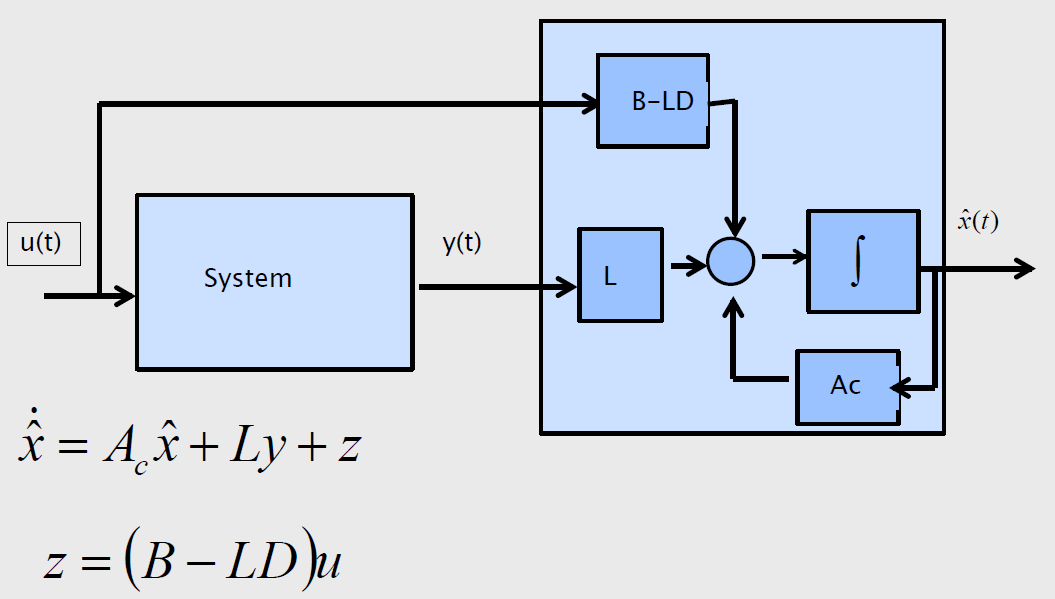

Design of our system and observer.

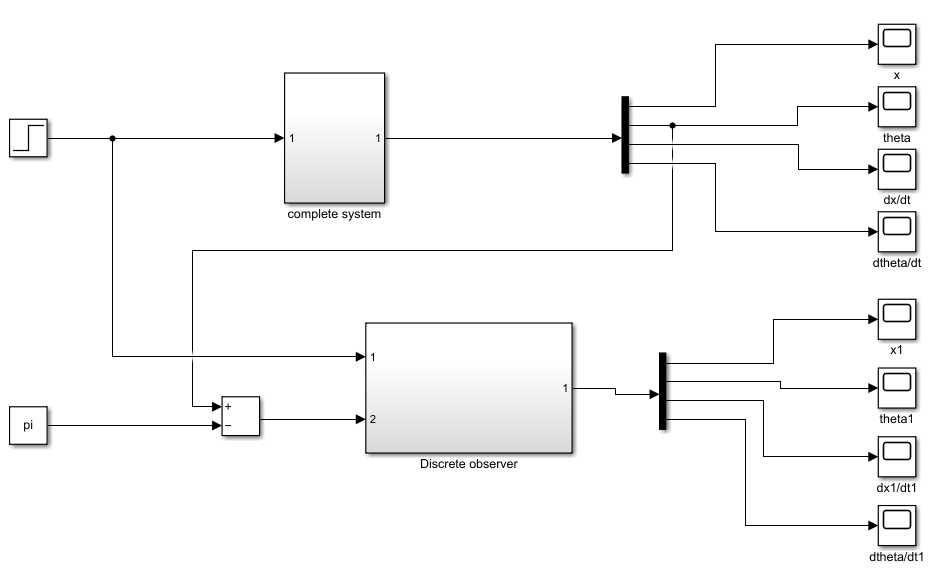

And our discrete observer looks like this.

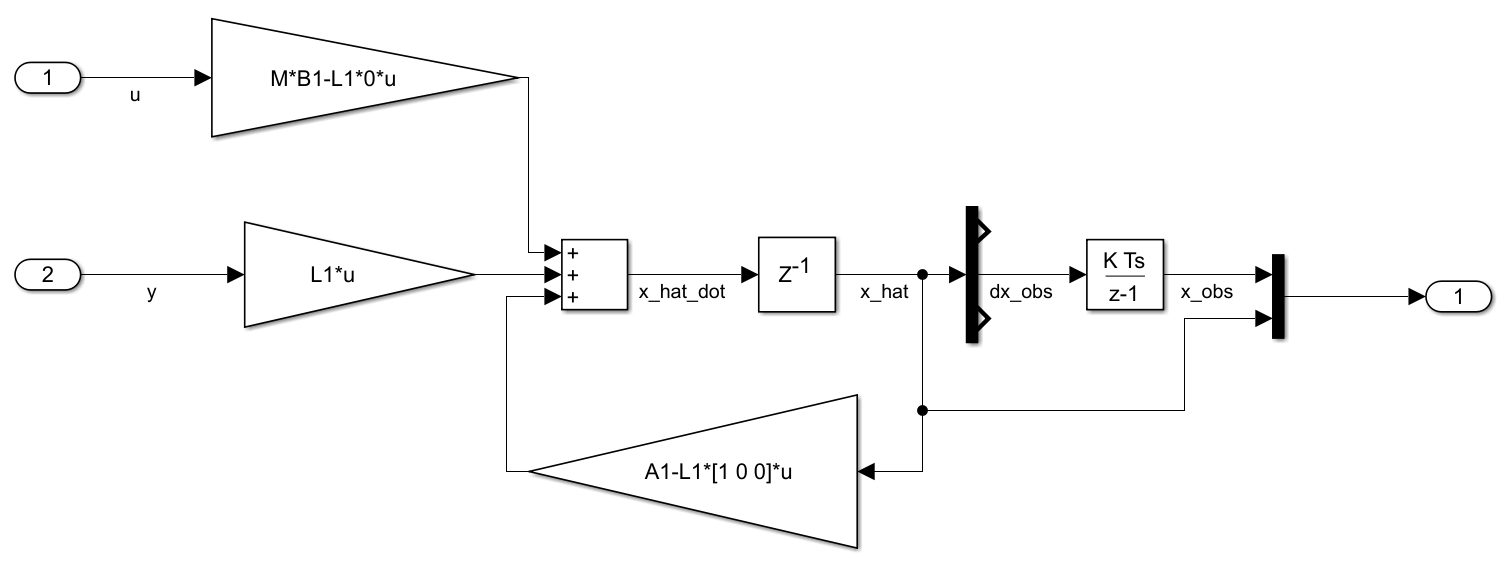

And we simulate the model.

sim('modelcomplet.mdl')

### c) Compare the estate estimation with the non linear simulation.

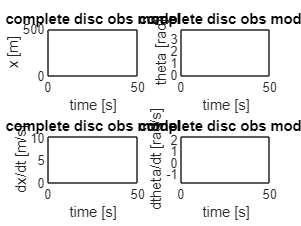

figure
subplot(2,2,1)
plot(x(:,1),x(:,2))
hold on
plot(x(:,1),x7(:,2),'r')
xlabel('time [s]')
ylabel('x [m]')
title('complete disc obs model')
subplot(2,2,2)
plot(x(:,1),theta(:,2))
hold on
plot(x(:,1),theta7(:,2),'r')
xlabel('time [s]')
ylabel('theta [rad]')
title('complete disc obs model')
subplot(2,2,3)
plot(x(:,1),dx(:,2))
hold on
plot(x(:,1),dx7(:,2),'r')
xlabel('time [s]')
ylabel('dx/dt [m/s]')
title('complete disc obs model')
subplot(2,2,4)
plot(x(:,1),dtheta(:,2))
hold on
plot(x(:,1),dtheta7(:,2),'r')
xlabel('time [s]')
ylabel('dtheta/dt [rad/s]')
title('complete disc obs model')

In the following graph we can see the nonlinear model (blue) and our state estimation (red). We were able to observe model only taking theta and then calculating position x from velocity. We can see that our theta and dtheta estimation is quite precise but x and dx are not, because of our A matrix reduction and only observing theta.